## Association of clinically significant MR with physical exam variables

Here I want to explore the group characteristics of the cohort consisting of subjects with moderate to severe MR. One of the motivations for this investigation is to get a sense of how good cardiac auscultation is at predicting MR. Perhaps it makes more sense to investigate other ways to detect the disease, and perhaps we should not waste too much energy on trying to predict the disease based on asucultation when there are more effective ways of predicting it. First we define the dataset.

Ind = HSdata0.MRGRADE_T72>=3;
dataSick    = HSdata0(Ind,:);
dataHealthy = HSdata0(~Ind,:);

What is the **gender** **distribution** of the disease?

mean(dataSick.SEX_T7==1)

ans = 0.5034

mean(dataHealthy.SEX_T7==1)

ans = 0.4529

We see that the **males** are **overrepresented **and that Gender is **significant**. What about **age**?

mean(dataSick.AGE_T7)

ans = 68.9589

mean(dataHealthy.AGE_T7)

ans = 63.2123

As expected, AR is **associated** with **old** age, and age is **significant**. Dyspnoe, or laboured **breathing**, is an important risk factor.

mean(dataSick.DYSPNEA_FAST_UPHILL_T7==1,'omitnan')

ans = 0.4452

mean(dataHealthy.DYSPNEA_FAST_UPHILL_T7,'omitnan')

ans = 0.3800

We see that there is a significant difference of about 6%. Dyspnea is **significant**. Is the "fast uphill" better at separating the two cohorts?

mean(dataSick.DYSPNEA_CALMLY_FLAT_T7==1,'omitnan')

ans = 0.0171

mean(dataHealthy.DYSPNEA_CALMLY_FLAT_T7==1,'omitnan')

ans = 0.0278

mean(dataSick.DYSPNOE_WASHING_DRESSING_T7==1,'omitnan')

ans = 0.0411

mean(dataHealthy.DYSPNOE_WASHING_DRESSING_T7==1,'omitnan')

ans = 0.0299

mean(dataSick.DYSPNOE_REST_T7==1,'omitnan')

ans = 0.0103

mean(dataHealthy.DYSPNOE_REST_T7==1,'omitnan')

ans = 0.0054

We are probably best of using the fast uphill test. Lets have a look at whether or not chest pain predicts AR.

mean(dataSick.CHEST_PAIN_FAST_T7==1,'omitnan')

ans = 0.1267

mean(dataHealthy.CHEST_PAIN_FAST_T7==1,'omitnan')

ans = 0.0822

it predicts it somewhat. Next let have a look at BMI. It is concievable that fat people are more likely to have AR.

mean(dataSick.BMI_T7,'omitnan')

ans = 26.2353

mean(dataHealthy.BMI_T7,'omitnan')

ans = 27.3328

BMI is actually somewhat lower for the AR cohort, but that is likely due to the fact that AR corellates strongly with age, and old people tend to be underweight. What about smoking status?

mean(dataSick.SMOKE_DAILY_Q2_T7==1,'omitnan')

ans = 0.0616

mean(dataHealthy.SMOKE_DAILY_Q2_T7==1,'omitnan')

ans = 0.1252

actually lower prevalence of smoking amongst sick people, but not by much. What about blood pressure?

mean(dataSick.HIGH_BLOOD_PRESSURE_T7>=1,'omitnan')

ans = 0.3904

mean(dataHealthy.HIGH_BLOOD_PRESSURE_T7>=1,'omitnan')

ans = 0.3576

Not a very strong predictor. Next we look at Heart attack:

mean(dataSick.HEART_ATTACK_T7>=1,'omitnan')

ans = 0.1267

mean(dataHealthy.HEART_ATTACK_T7>=1,'omitnan')

ans = 0.0561

No surprises there, there is higher prevalence of heart attack in the AR group. It is noteworthy however that only 12.7% of the MR group have had a heart attack. I thought it would be more.

mean(dataSick.HEART_FAILURE_T7>=1,'omitnan')

ans = 0.0925

mean(dataHealthy.HEART_FAILURE_T7>=1,'omitnan')

ans = 0.0240

Same conclusion as above.

mean(dataSick.COUGH_DAILY_T7>=1,'omitnan')

ans = 0.1712

mean(dataHealthy.COUGH_DAILY_T7>=1,'omitnan')

ans = 0.1660

Coughing is not a predictor of MR. 

Next lets have a look at **PO2** **max**, which measures blood oxygen saturation, and how effective the lungs are at pulling O2 from the air.

mean(dataSick.PO2_T72,'omitnan')

ans = 97.5918

mean(dataHealthy.PO2_T72,'omitnan')  

ans = 97.6538

No difference. What about Lung capacity as measured by a **spirometry**?

mean(dataSick.PULSESPIRO_T72<60,'omitnan')

ans = 0.4178

mean(dataHealthy.PULSESPIRO_T72<60,'omitnan') 

ans = 0.3212

A significant group difference. The AR group had a 41.8% prevalence of scoring less than 60 on the test, whereas for the healthy group the number was only 32.1%. Finally, for good measure, we look at the predictive value of maximum murmur grade for predicting AR.

mean(dataSick.maxMeanMurGrade>=2,'omitnan')

ans = 0.1644

mean(dataHealthy.maxMeanMurGrade>=2,'omitnan') 

ans = 0.0969

risk of murmur grade >= 2 is **16.44%** for the sick group, and **9.7%** for the healthy group. This shows that as seemingly bad as cardiac auscultation is at predicting MR, it is still the **most predictive** variable amongst the variables collected during a physical examination.

### conclusions:

Age, sex, dyspnea fast upphill, high bloodpressure, chest pain, pulse spiro, and murmur grade are significant predictors of significant AR. Let us throw them all into a regression model, but first we have to see how much **data is available** to model.

data = HSdata0;
Inan = isnan(data.SEX_T7)+isnan(data.AGE_T7)+isnan(data.DYSPNEA_FAST_UPHILL_T7)+...
    isnan(data.HIGH_BLOOD_PRESSURE_T7) + isnan(data.PULSESPIRO_T72) +...
    isnan(data.CHEST_PAIN_FAST_T7) + isnan(data.MRGRADE_T72);
Inan = (Inan>=1);
sum(Inan)

ans = 231

we loose 231 samples.  Will exclusion of the nan entries bias our findings?

mean(data.MRGRADE_T72(~Inan)>=3)

ans = 0.1286

mean(data.MRGRADE_T72>=3)

ans = 0.1372

sum(~Inan)

ans = 1898

 We have 1% decrease in prevalence of significant MR, which we conclude to be insiginificant source of bias. Now we **model**.

dataMdl = data(~Inan,:);
MRsig = table(dataMdl.MRGRADE_T72>=3,'VariableNames',{'MRsig'});
dataMdl = [dataMdl, MRsig];

dataMdl.SEX_T7 = categorical(dataMdl.SEX_T7);
dataMdl.DYSPNEA_FAST_UPHILL_T7 = categorical(dataMdl.DYSPNEA_FAST_UPHILL_T7);
dataMdl.HIGH_BLOOD_PRESSURE_T7 = categorical(dataMdl.HIGH_BLOOD_PRESSURE_T7>0);
dataMdl.CHEST_PAIN_FAST_T7     = categorical(dataMdl.CHEST_PAIN_FAST_T7);

formula = strcat('MRsig ~ AGE_T7 + SEX_T7 + HIGH_BLOOD_PRESSURE_T7 +',...
     'DYSPNEA_FAST_UPHILL_T7 + CHEST_PAIN_FAST_T7 + PULSESPIRO_T72')

formula = 'MRsig ~ AGE_T7 + SEX_T7 + HIGH_BLOOD_PRESSURE_T7 +DYSPNEA_FAST_UPHILL_T7 + CHEST_PAIN_FAST_T7 + PULSESPIRO_T72'

glm = fitglm(dataMdl,formula,'distr','binomial')

glm = Generalized linear regression model:
    logit(MRsig) ~ 1 + AGE_T7 + SEX_T7 + HIGH_BLOOD_PRESSURE_T7 + CHEST_PAIN_FAST_T7 + DYSPNEA_FAST_UPHILL_T7 + PULSESPIRO_T72
    Distribution = Binomial

Estimated Coefficients:
                                   Estimate        SE         tStat        pValue  
                                   _________    _________    ________    __________

    (Intercept)                      -3.7217      0.68623     -5.4235    5.8459e-08
    AGE_T7                            0.0553    0.0076745      7.2057    5.7766e-13
    SEX_T7_1                        0.050877      0.14265     0.35665       0.72135
    HIGH_BLOOD_PRESSURE_T7_true     -0.21371      0.15051     -1.4199       0.15564
    CHEST_PAIN_FAST_T7_1           -0.041779      0

Get **performance curve** for prediction of significant MR:

glm.predict

ans =     0.1481
    0.0963
    0.0992
    0.1142
    0.3071
    0.1361
    0.2216
    0.1909
    0.1707
    0.1401


[X,Y,T,AUC] = perfcurve(dataMdl.MRsig, glm.predict, true)

X =          0
    0.0006
    0.0012
    0.0012
    0.0018
    0.0024
    0.0030
    0.0036
    0.0042
    0.0042


Y =          0
         0
         0
    0.0041
    0.0041
    0.0041
    0.0041
    0.0041
    0.0041
    0.0082


T =     0.4936
    0.4936
    0.4394
    0.4255
    0.4121
    0.3814
    0.3781
    0.3733
    0.3703
    0.3665


AUC = 0.6777

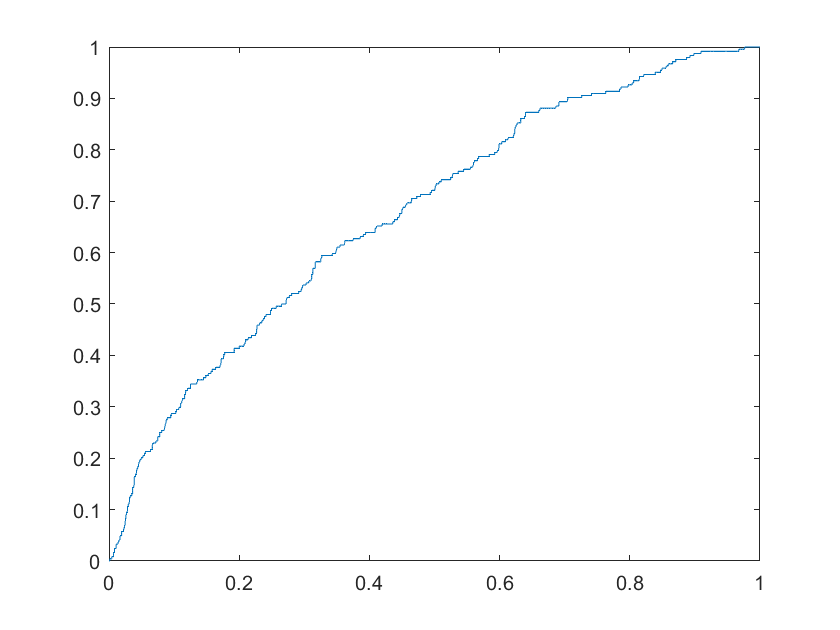

clf
plot(X,Y)

We get an AUC of **67.8% for predicting clinically significant AR**. This is ok. What happens if we model using **only** murmur grade?

[X,Y,~,AUC] = perfcurve(dataMdl.MRsig, dataMdl.maxMeanMurGrade, true)

X =          0
    0.0018
    0.0054
    0.0109
    0.0212
    0.0417
    0.0647
    0.0979
    0.1324
    0.1729


Y =          0
    0.0082
    0.0164
    0.0369
    0.0574
    0.0861
    0.1025
    0.1475
    0.2008
    0.2418


AUC = 0.5342

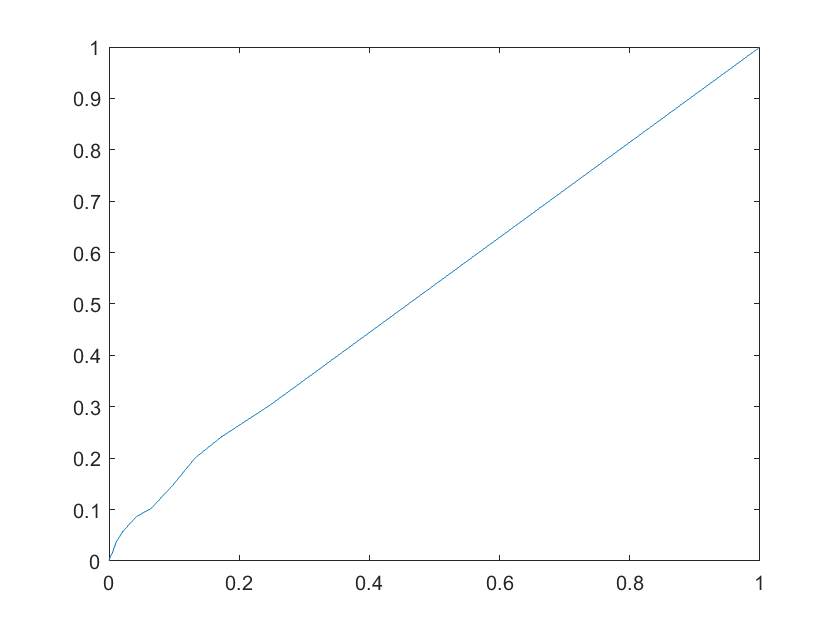

clf
plot(X,Y);

When we use only max murmur grade to predict AR, we get an AUC of **53.4%**. This is **not good,** but it agrees with the low connection we have found before between MR and murmur grade. Cleary, using the other covariates results in a much better model. Before we conclude that murmur is useless as predictor of MR, let us see if the using measurements from **other locations** improves predictive ability. 

[X,Y,~,AUC1] = perfcurve(dataMdl.MRsig, dataMdl.Murmur_1_grade_ref_ny_T72, true)

X =          0
    0.0018
    0.0030
    0.0085
    0.0175
    0.0363
    0.0550
    0.0895
    0.1221
    0.1578


Y =          0
    0.0041
    0.0164
    0.0328
    0.0451
    0.0615
    0.0697
    0.1025
    0.1557
    0.1885


AUC1 = 0.5211

[X,Y,~,AUC2] = perfcurve(dataMdl.MRsig, dataMdl.Murmur_2_grade_ref_ny_T72, true)

X =          0
    0.0012
    0.0024
    0.0060
    0.0127
    0.0260
    0.0399
    0.0568
    0.0816
    0.1288


Y =          0
         0
    0.0041
    0.0164
    0.0369
    0.0533
    0.0738
    0.0943
    0.1107
    0.1639


AUC2 = 0.5192

[X,Y,~,AUC3] = perfcurve(dataMdl.MRsig, dataMdl.Murmur_3_grade_ref_ny_T72, true)

X =          0
    0.0006
    0.0012
    0.0018
    0.0091
    0.0157
    0.0254
    0.0417
    0.0605
    0.0834


Y =          0
    0.0041
    0.0041
    0.0123
    0.0246
    0.0492
    0.0656
    0.0984
    0.1189
    0.1393


AUC3 = 0.5424

[X,Y,~,AUC4] = perfcurve(dataMdl.MRsig, dataMdl.Murmur_4_grade_ref_ny_T72, true)

X =          0
    0.0018
    0.0036
    0.0054
    0.0121
    0.0224
    0.0320
    0.0417
    0.0550
    0.0810


Y =          0
         0
    0.0082
    0.0246
    0.0451
    0.0615
    0.0902
    0.1107
    0.1270
    0.1393


AUC4 = 0.5311

[X,Y,~,AUC5] = perfcurve(dataMdl.MRsig, dataMdl.maxMeanMurGrade, true)

X =          0
    0.0018
    0.0054
    0.0109
    0.0212
    0.0417
    0.0647
    0.0979
    0.1324
    0.1729


Y =          0
    0.0082
    0.0164
    0.0369
    0.0574
    0.0861
    0.1025
    0.1475
    0.2008
    0.2418


AUC5 = 0.5342


[AUC1,AUC2,AUC3,AUC4,AUC5]'

ans =     0.5211
    0.5192
    0.5424
    0.5311
    0.5342


Finally, lets try adding murmur grade to the **full model**

formula = strcat('MRsig ~ AGE_T7 + SEX_T7 + HIGH_BLOOD_PRESSURE_T7 +',...
     'DYSPNEA_FAST_UPHILL_T7 + CHEST_PAIN_FAST_T7 + PULSESPIRO_T72 + Murmur_3_grade_ref_ny_T72')

formula = 'MRsig ~ AGE_T7 + SEX_T7 + HIGH_BLOOD_PRESSURE_T7 +DYSPNEA_FAST_UPHILL_T7 + CHEST_PAIN_FAST_T7 + PULSESPIRO_T72 + Murmur_3_grade_ref_ny_T72'

glm = fitglm(dataMdl,formula,'distr','binomial')

glm = Generalized linear regression model:
    logit(MRsig) ~ 1 + AGE_T7 + SEX_T7 + HIGH_BLOOD_PRESSURE_T7 + CHEST_PAIN_FAST_T7 + DYSPNEA_FAST_UPHILL_T7 + PULSESPIRO_T72 + Murmur_3_grade_ref_ny_T72
    Distribution = Binomial

Estimated Coefficients:
                                   Estimate        SE          tStat        pValue  
                                   _________    _________    _________    __________

    (Intercept)                      -3.6297      0.68618      -5.2897     1.225e-07
    AGE_T7                          0.052674    0.0077707       6.7785    1.2141e-11
    SEX_T7_1                         0.06379       0.1431      0.44577       0.65577
    HIGH_BLOOD_PRESSURE_T7_true     -0.23781      0.15149      -1.5698       0.11646
    CHEST_PAIN_FAST_T7_1  


[X,Y,T,AUC] = perfcurve(dataMdl.MRsig, glm.predict, true)

X =          0
    0.0006
    0.0012
    0.0018
    0.0018
    0.0018
    0.0024
    0.0030
    0.0036
    0.0036


Y =          0
         0
         0
         0
    0.0041
    0.0082
    0.0082
    0.0082
    0.0082
    0.0123


T =     0.4725
    0.4725
    0.4703
    0.4426
    0.4274
    0.4211
    0.4174
    0.4158
    0.4156
    0.4004


AUC = 0.6826

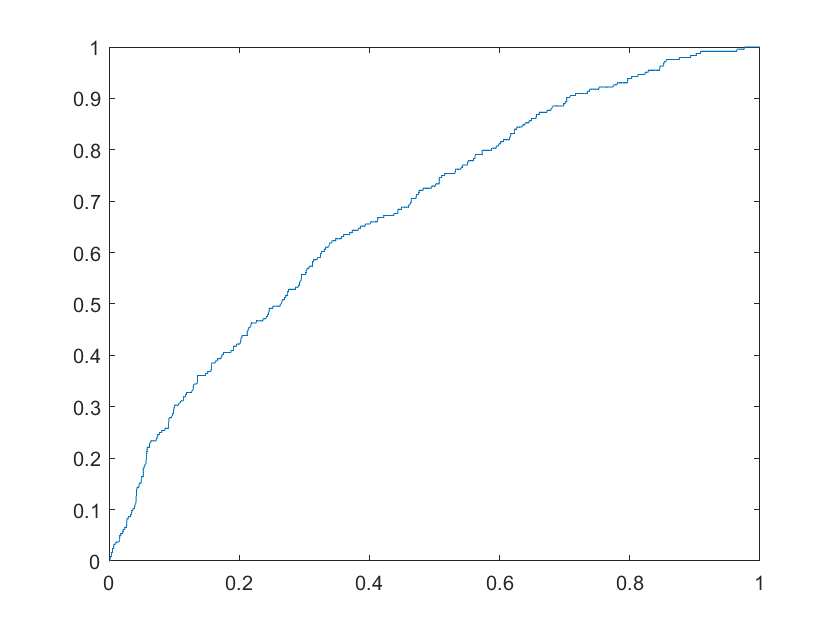

clf
plot(X,Y)

We get an AUC of **68.3%**, which is an increase of **0.5%**, which is not very significant, but **murmur** grade in location 4 is on the border of being statisctically **significant**. Furthermore, blood pressure and chest pain have very insignificant p-values, lets try eliminating them from the model.

formula = strcat('MRsig ~ AGE_T7 +',...
     'DYSPNEA_FAST_UPHILL_T7 + PULSESPIRO_T72 + Murmur_3_grade_ref_ny_T72')

formula = 'MRsig ~ AGE_T7 +DYSPNEA_FAST_UPHILL_T7 + PULSESPIRO_T72 + Murmur_3_grade_ref_ny_T72'

glm = fitglm(dataMdl,formula,'distr','binomial')

glm = Generalized linear regression model:
    logit(MRsig) ~ 1 + AGE_T7 + DYSPNEA_FAST_UPHILL_T7 + PULSESPIRO_T72 + Murmur_3_grade_ref_ny_T72
    Distribution = Binomial

Estimated Coefficients:
                                 Estimate        SE         tStat       pValue  
                                 _________    _________    _______    __________

    (Intercept)                      -3.45      0.66982    -5.1506    2.5968e-07
    AGE_T7                        0.050003     0.007507     6.6609    2.7223e-11
    DYSPNEA_FAST_UPHILL_T7_1       0.25393      0.14391     1.7646      0.077639
    PULSESPIRO_T72               -0.030503    0.0071773    -4.2499    2.1384e-05
    Murmur_3_grade_ref_ny_T72       0.1551     0.088808     1.7465      0.080721


1898 observat


[X,Y,T,AUC] = perfcurve(dataMdl.MRsig, glm.predict, true);
AUC

AUC = 0.6802

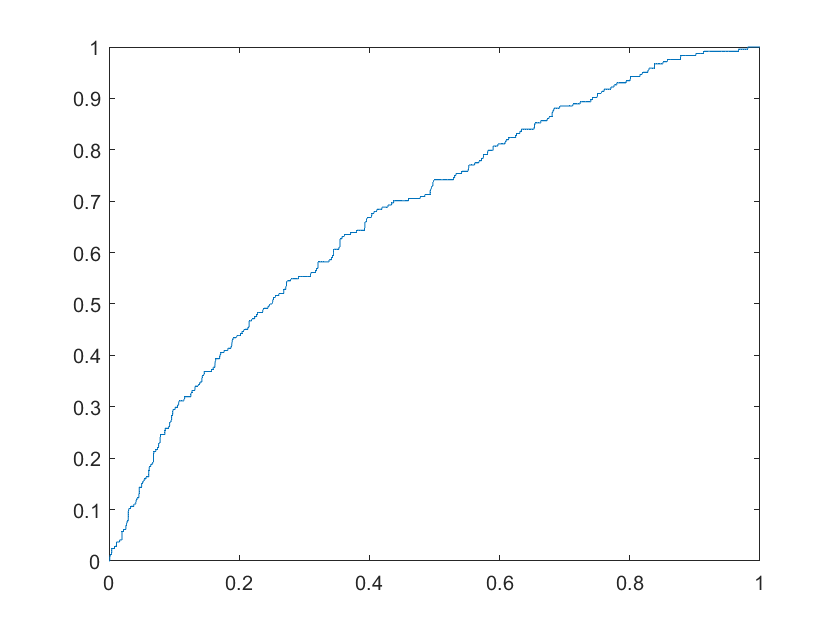

clf
plot(X,Y)

The AUC is now **68.0%, **which is only a drop of about **0.3%.** We conclude that to predict clinically significant MR, **age**, **dyspnea**, and pulse **spirometry** contribute **significantly**. **Murmur** grade is a **poor** predictor of **MR**.